# *arael - *simulation guidelines

clearvars
close all
clc

IMPORTANT: Remember to set the MATLAB working directory to the one that contains the 'arael' folder. Then select the 'arael' folder and use the command 'Add to Path/Selected Folder(s) and Subfolder(s)'.

Arael is an orbit propagation tool that allows the user to choose between 4 modaliites, allowing to compromise accuracy and speed.

The input is composed of 5 *struct elements *containing information about:

- Initial conditions (time, space)

- Reference system

- Perturbation environment

- Satellite characteristics

- Settings

## Initial conditions

Let's start by setting the initial conditions in term of time an space.

The time is defined using two elements:

- Integration timespan: the time-step of the integration, ranging from 0 to the desired duration of the propagation and subdivided in steps. The subdivision can be of any kind. Unit is seconds.

- Initial time in UTC format.

Let's set the timespan to 10 days subdivided by 60 seconds.

init_cond.tSpan = 0:60:10*24*3600; % [s]

And the initial time to the 2nd Genuary 2024 at 12:00:00.

init_cond.utc0 = '2024-02-05 05:17:42.819936 UTC';

For what regrads the initial state, let's define it in terms of position and velocity.

p0 = [-3.8390486e04; -1.8598850e04; -0.2190072e04]; % position [km]
v0 = [1.38103802; -2.61775385; -0.66841401]; % velocity [km/s]
init_cond.x0 = [p0;v0];

## Reference system

Since *arael *makes use of the* spice *toolbox delevoped by NASA, a refrence system can be defined in a simplified way.

Let's start from the orientation of the inertial axes. In this case we will use the J2000 reference system parallel to Earth Equator. For more choices of inertial axes the user can use the command '`help arael'`.

ref_sys.inertial = 'J2000';

Now let's set the center of the reference system, the observer body. Here we will use the Earth as center, which means that we will propagate an orbit around the Earth. Also this time, use the command '`help arael`' for more choices.

ref_sys.obs = 'EARTH';

## Perturbation Environment

We will now set the environment in term of perturbations. Depending on the selected propagation mode, propagations are taken into account in different ways. The can be subdivided into 4 sections:

- Gravity

- Third-body

- Solar Radiation Pressure

- Drag

### Gravity

The gravitational field is considered as a perturbing force added to the basic two-body problems. The way it is taken into account depends on the integration mode, more info about it are shown by the command '`help arael`'. Basically, the user sets the degree to which extension the gravity field will be computed. 

In this case we will set it at 10, since we will be using the '*hifi' *mode, which allows for high-order fields based on spherical harmonic expansions. Using* 'approx' *or *'average'  *imply an approximated version of the gravitational field, which will be truncated to lower terms. Type '`help arael`' for more info.

perturb.n = 10;

### Third-body

Next step is to set the third-body effects. This is done by simply imputing a cell containing the names of the perturbing bodies. In this case, since we're integrating an orbit around the Moon, we will add only Sun and Moon perturbations.

perturb.TB = {'SUN','MOON'};

### Solar Radiation Pressure

Solar Radiation Pressure is an on/off effect. It depends on the physical characteristics of the spacecraft, which will be described later. In this case we won't consider it in our simulation.

perturb.SRP = 'off';

### Drag

Drag has not been implemented yet.

## Satellite characteristics

Here we will set the physical and geometrical properties of the spacecraft, such as mass, surface and reflectivity index.

spacecraft.m = 10; % mass [kg]
spacecraft.A = 2; % cross-surface [m^2]
spacecraft.cR = 1.8; % reflection coefficient [-]

Those are not necessary in case SRP is not taken into account. If left blank, they will be set to default.

## Settings

Now we will choose the propagation method. In this case we will use '*hifi'* for a very accurate propagation. Type '`help arael`' for more info about the other possible modalities.

settings.mode = 'hifi';

Lastly, let's set the relative and absolute accuracy for the integrator.

settings.rel_tol = 1e-09;
settings.abs_tol = 1e-09;

## Propagation

Now let's call the propagator with the input we just built and save the output.

[t,y] = arael(init_cond,ref_sys,perturb,settings,spacecraft);

Computing expansion coefficients...
Computing harmonic functions...
Propagating the orbit...
Elapsed time is 0.214763 seconds.


## Post-processing

Let's plot the 3D orbit in space.

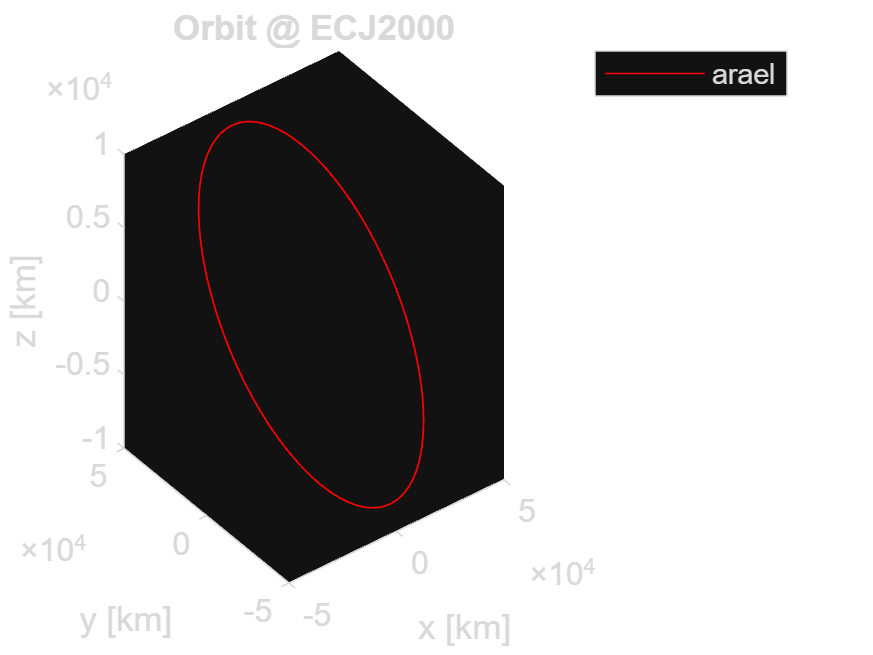

% 3D plot
figure(1)
plot3(y(:,1),y(:,2),y(:,3),'r',DisplayName='arael')
xlabel('x [km]')
ylabel('y [km]')
zlabel('z [km]')
title('Orbit @ ECJ2000')
legend

Now we need to convert the cartesian state into keplerian elements and then visualize them.

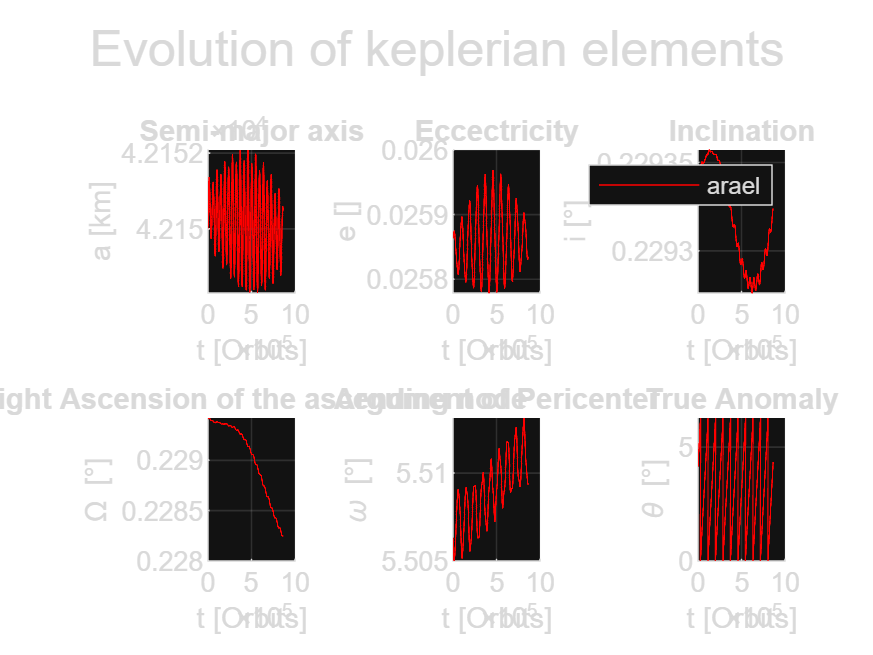

% retreieve keplerians
kep = zeros(length(t),6);
mu = 3.9860e+05;

for i = 1:length(t)
    kep(i,:) = car2kep(y(i,:),mu);
end

% plot keplerians
figure(2)
sgtitle('Evolution of keplerian elements')
subplot(2,3,1)
hold on
plot(t, kep(:,1),'r')
title('Semi-major axis')
xlabel('t [Orbits]')
ylabel('a [km]')
grid on
subplot(2,3,2)
hold on
plot(t, kep(:,2),'r')
title('Eccectricity')
xlabel('t [Orbits]')
ylabel('e []')
grid on
subplot(2,3,3)
hold on
plot(t, kep(:,3),'r',DisplayName='arael')
title('Inclination')
xlabel('t [Orbits]')
ylabel('i [°]')
legend
grid on
subplot(2,3,4)
hold on
plot(t, kep(:,4),'r')
title('Right Ascension of the ascending node')
xlabel('t [Orbits]')
ylabel('\Omega [°]')
grid on
subplot(2,3,5)
hold on
plot(t, kep(:,5),'r')
title('Argument of Pericenter')
xlabel('t [Orbits]')
ylabel('\omega [°]')
grid on
subplot(2,3,6)
hold on
plot(t, wrapTo360(kep(:,6)),'r')
title('True Anomaly')
xlabel('t [Orbits]')
ylabel('\theta [°]')
grid on

## Comparison

We can now compare the results using both GMAT and SGP4 with the TLE of a selcted celestial object. In this case we will use the Breeze Rocket Body (ID [26373](https://www.space-track.org/basicspacedata/query/class/satcat/NORAD_CAT_ID/26373/format/html/emptyresult/show)) for comparison. The TLE were downloaded from Space-Track (www.spacetrack.org).

### GMAT

A simulation was run using GMAT with same initial conditions and perturbations. Results are stored in the following folder.

gmat = 'arael\utils\gmat_debug\EARTH_debug_sgp4.txt';

Let's load the results and perform the same plot as before.

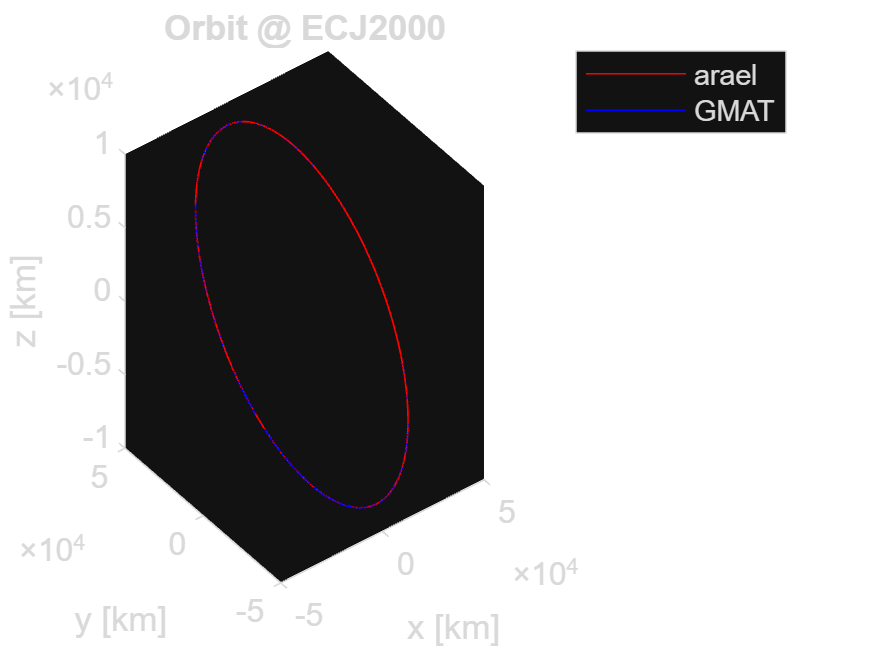

% load data
data = readmatrix(gmat);
y_gmat = data(:,2:7);
t_gmat = data(:,8);

% retreieve keplerians
kep_gmat = zeros(length(t),6);

for i = 1:length(t)
    kep_gmat(i,:) = car2kep(y_gmat(i,:),mu);
end

% 3D plot
figure(1)
hold on
plot3(y_gmat(:,1),y_gmat(:,2),y_gmat(:,3),'b',DisplayName='GMAT')
xlabel('x [km]')
ylabel('y [km]')
zlabel('z [km]')
title('Orbit @ ECJ2000')

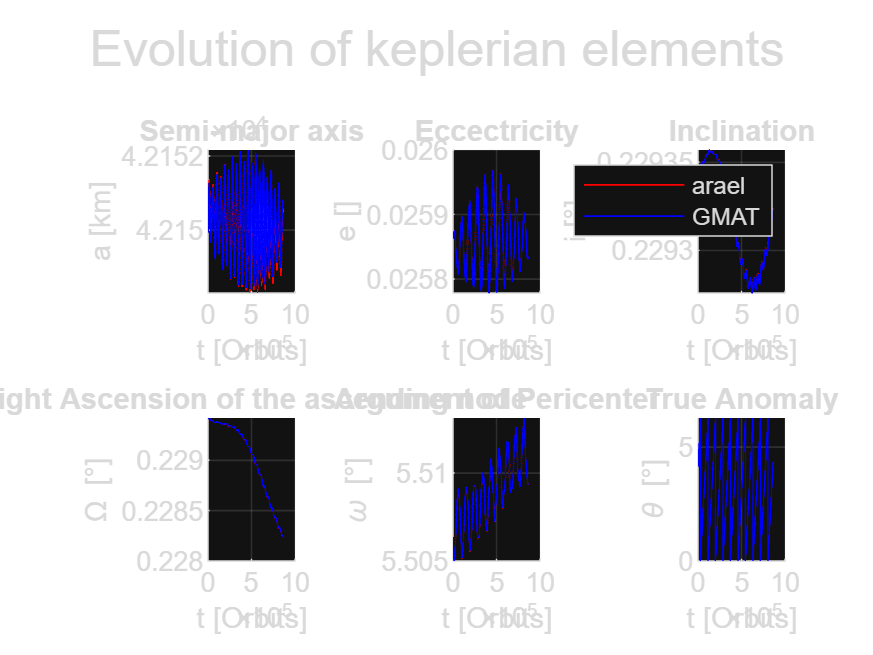

legend

% plot keplerians
figure(2)
sgtitle('Evolution of keplerian elements')
subplot(2,3,1)
hold on
plot(t_gmat,kep_gmat(:,1),'b')
title('Semi-major axis')
xlabel('t [Orbits]')
ylabel('a [km]')
grid on
subplot(2,3,2)
hold on
plot(t_gmat,kep_gmat(:,2),'b')
title('Eccectricity')
xlabel('t [Orbits]')
ylabel('e []')
grid on
subplot(2,3,3)
hold on
plot(t_gmat,kep_gmat(:,3),'b',DisplayName='GMAT')
title('Inclination')
xlabel('t [Orbits]')
ylabel('i [°]')
grid on
legend
subplot(2,3,4)
hold on
plot(t_gmat,kep_gmat(:,4),'b')
title('Right Ascension of the ascending node')
xlabel('t [Orbits]')
ylabel('\Omega [°]')
grid on
subplot(2,3,5)
hold on
plot(t_gmat,kep_gmat(:,5),'b')
title('Argument of Pericenter')
xlabel('t [Orbits]')
ylabel('\omega [°]')
grid on
subplot(2,3,6)
hold on
plot(t_gmat,kep_gmat(:,6),'b')
title('True Anomaly')
xlabel('t [Orbits]')
ylabel('\theta [°]')
grid on

### SGP4

Let's propagate the orbit using also SGP4.

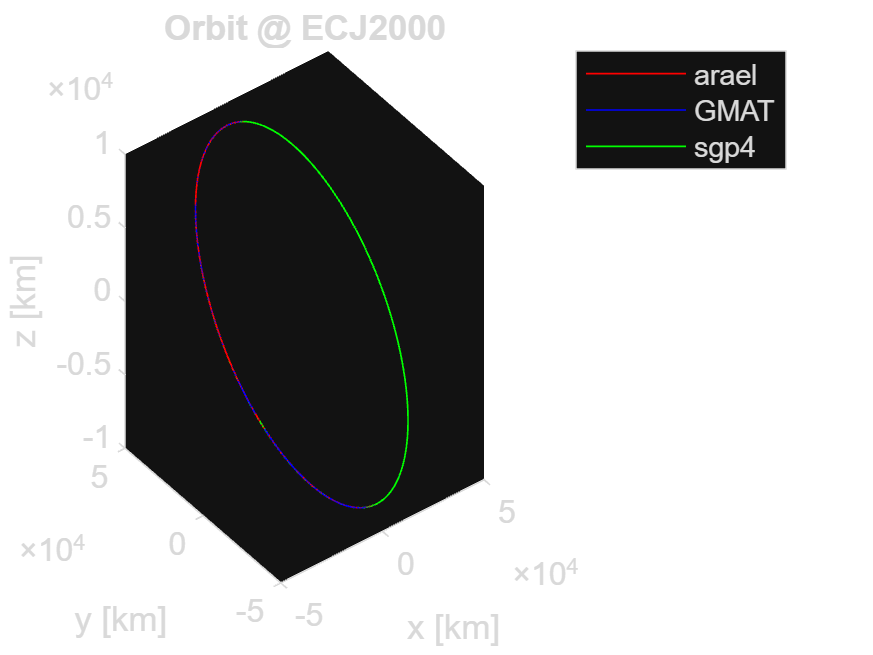

%%% sgp4
typerun    = 'u';  % user-provided inputs to SGP4 Matlab function
opsmode    = 'a';  % afspc approach ('air force space command')
whichconst =  72;  % WGS72 constants (radius, gravitational parameter)
et0 = cspice_str2et(init_cond.utc0);

% load the tle (breeze 26373)
tle_1 = '1 26373U 00029B   24036.22063449 -.00000084  00000-0  00000-0 0  9990';
tle_2 = '2 26373  13.1105  12.8500 0258164 316.2858 239.8887  1.00328814 86779';

% compute state
satrec = twoline2rv(tle_1, tle_2, typerun,'e', opsmode, whichconst);

% retrieve tle epoch
[year,mon,day,hr,min,sec] = invjday(satrec.jdsatepoch, satrec.jdsatepochf);
sat_epoch_str = sprintf('%d-%02d-%02dT%02d:%02d:%02.6f', [year,mon,day,hr,min,sec]);
sat_epoch_et = cspice_str2et(sat_epoch_str);

% integrate using sgp4
tSpan_sgp4 = (init_cond.tSpan + et0 - sat_epoch_et)/60;
r_teme = zeros(3, length(tSpan_sgp4));
v_teme = zeros(3, length(tSpan_sgp4));

for i = 1:length(tSpan_sgp4) 
[~,r_teme(:,i),v_teme(:,i)] = sgp4(satrec,  tSpan_sgp4(i));
end

% convert from TEME to ECI
ateme = [0;0;0];
ttt = cspice_unitim(init_cond.tSpan + et0, 'ET', 'TDT')/cspice_jyear()/100;
arcsec2rad = pi/(180*3600);
dPsi = -0.113638*arcsec2rad;
dEps = -0.007048*arcsec2rad;
r_sgp4 = zeros(3, length(tSpan_sgp4));
v_sgp4 = zeros(3, length(tSpan_sgp4));

for i = 1:length(tSpan_sgp4) 
[r_sgp4(:,i), v_sgp4(:,i), ~] = teme2eci(r_teme(:,i), v_teme(:,i), ateme, ttt(i), dPsi, dEps);
end

y_sgp4 = [r_sgp4;v_sgp4]';
t_sgp4 = init_cond.tSpan;

%%% plot

% retreieve keplerians
kep_sgp4 = zeros(length(t),6);

for i = 1:length(t)
    kep_sgp4(i,:) = car2kep(y_sgp4(i,:),mu);
end

% 3D plot
figure(1)
hold on
plot3(y_sgp4(:,1),y_sgp4(:,2),y_sgp4(:,3),'g',DisplayName='sgp4')
xlabel('x [km]')
ylabel('y [km]')
zlabel('z [km]')
title('Orbit @ ECJ2000')

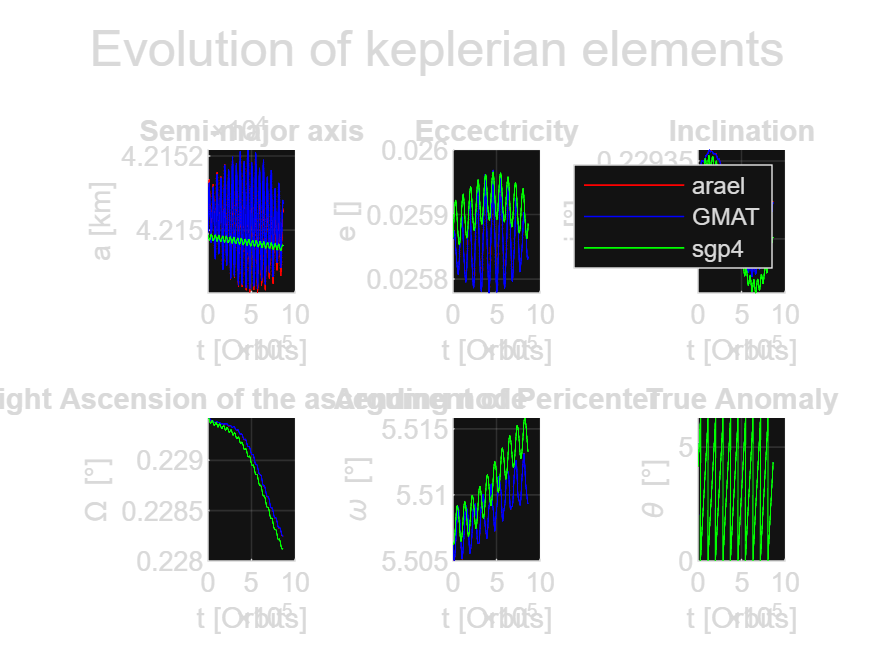



% plot keplerians
figure(2)
sgtitle('Evolution of keplerian elements')
subplot(2,3,1)
hold on
plot(t_sgp4,kep_sgp4(:,1),'g')
title('Semi-major axis')
xlabel('t [Orbits]')
ylabel('a [km]')
grid on
subplot(2,3,2)
hold on
plot(t_sgp4,kep_sgp4(:,2),'g')
title('Eccectricity')
xlabel('t [Orbits]')
ylabel('e []')
grid on
subplot(2,3,3)
hold on
plot(t_sgp4,kep_sgp4(:,3),'g',DisplayName='sgp4')
title('Inclination')
xlabel('t [Orbits]')
ylabel('i [°]')
grid on
legend
subplot(2,3,4)
hold on
plot(t_sgp4,kep_sgp4(:,4),'g')
title('Right Ascension of the ascending node')
xlabel('t [Orbits]')
ylabel('\Omega [°]')
grid on
subplot(2,3,5)
hold on
plot(t_sgp4,kep_sgp4(:,5),'g')
title('Argument of Pericenter')
xlabel('t [Orbits]')
ylabel('\omega [°]')
grid on
subplot(2,3,6)
hold on
plot(t_sgp4,kep_sgp4(:,6),'g')
title('True Anomaly')
xlabel('t [Orbits]')
ylabel('\theta [°]')
grid on